# Power-Split Hybrid Electric Vehicle Model with Direct Input

## Open the model

mdl = "PowerSplitHEV_system_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitHEV_DirectInput_setup

## Load inputs

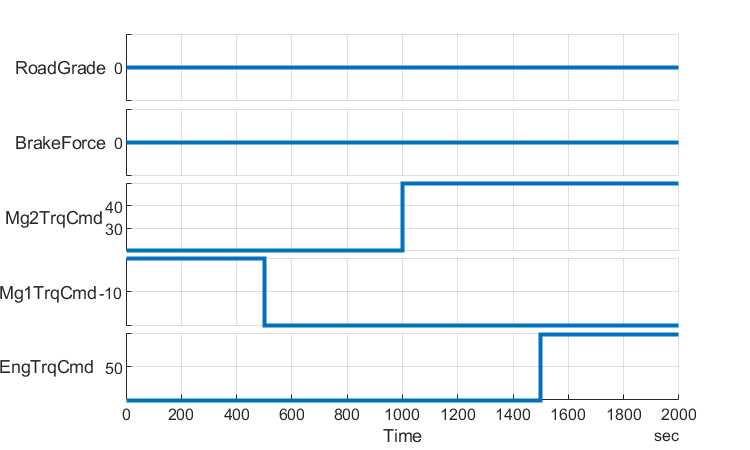

fig = figure;
[inputSignals_DirectIn, inputBus_DirectIn, t_end] = ...
  PowerSplitHEV_DirectInput_inputs( ...
    "PlotParent",fig, "InputPattern","power_split_drive" );

## Run simulation

% Set initial conditions

initial.highVoltageBatterySOC_pct = 85;
initial.hvBatteryCharge_Ah = ...
  batteryHighVoltage.nominalCharge_Ah * initial.highVoltageBatterySOC_pct/100;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override block parameters

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

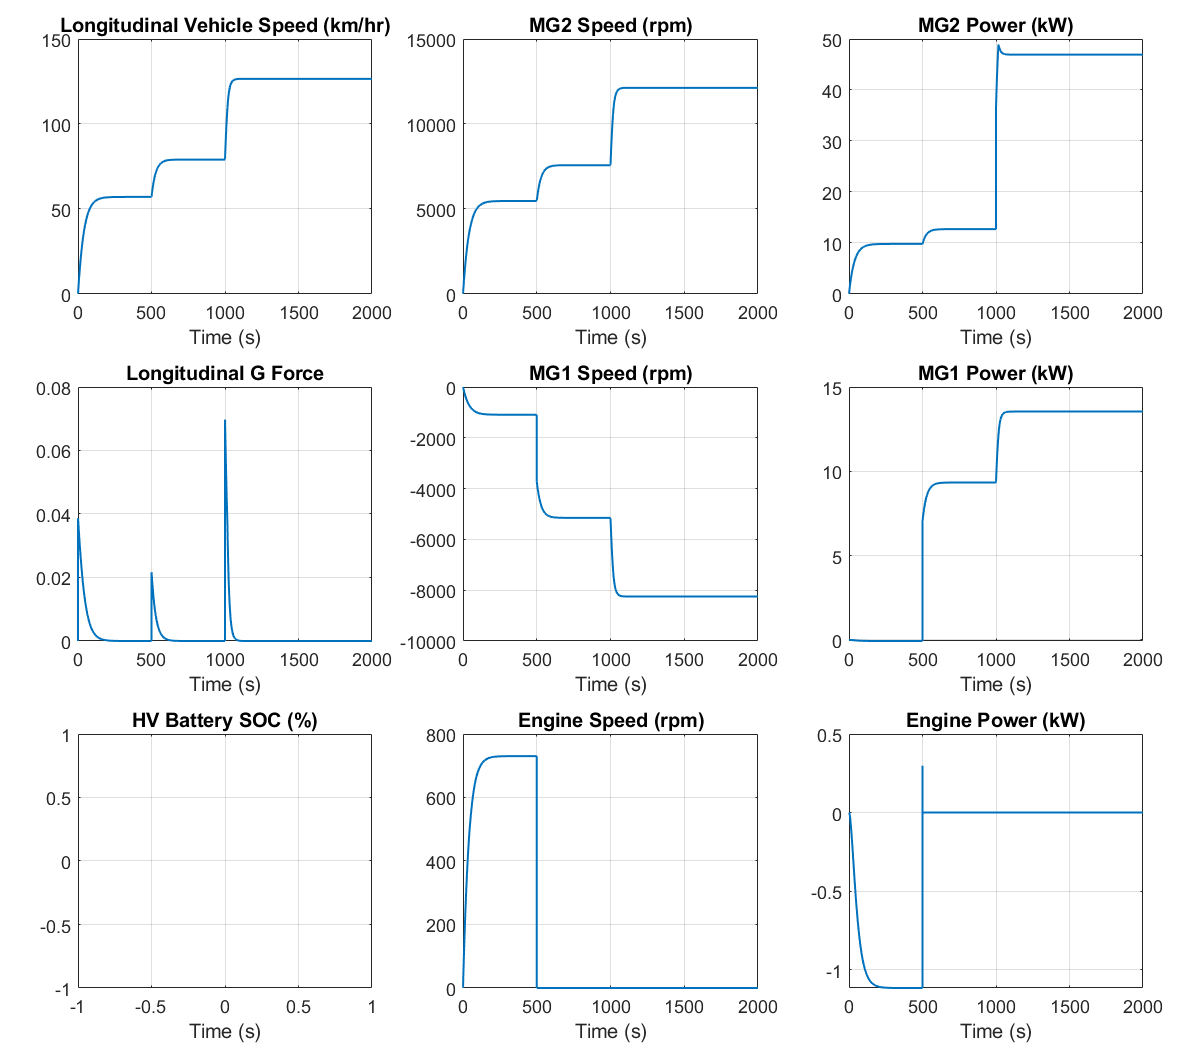

fig = figure;
PowerSplitHEV_plot_result_compact( "Dataset",out.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*